% MATLAB Code for Bode Plot Analysis of the Uncompensated System
% ---------------------------------------------------------------
% This script defines the open-loop transfer function and generates its
% Bode plot to analyze frequency response and stability margins.

% Clear workspace, command window, and close all figures for a clean run
clear;
clc;
close all;

% --- 1. Define the System ---
% Define the numerator and denominator of the open-loop transfer function G_ol(s).
% G_ol(s) = -10.07 / (s^2 + 1806s + 4843)
num_ol = [-10.07];       % Numerator coefficients
den_ol = [1, 1806, 4843]; % Denominator coefficients

% Create the transfer function object for the open-loop system.
G_ol = tf(num_ol, den_ol);

% Display the transfer function in the command window to verify.
disp('Open-Loop Transfer Function (G_ol):');

Open-Loop Transfer Function (G_ol):


G_ol


G_ol =
 
        -10.07
  -------------------
  s^2 + 1806 s + 4843
 
Continuous-time transfer function.
Model Properties


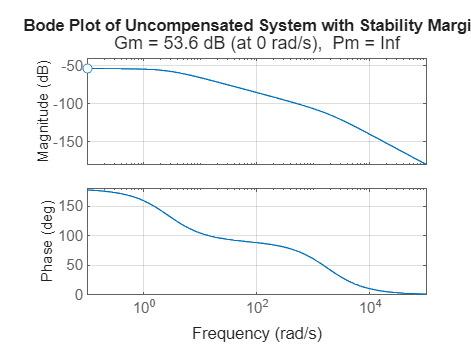


% --- 2. Generate and Display the Bode Plot with Margins ---
% Create a new figure window for the plot.
figure;

% Generate the Bode plot using the 'margin' command.
% This function plots the magnitude and phase response and automatically
% calculates and displays the Gain Margin (Gm) and Phase Margin (Pm).
margin(G_ol);

% --- 3. Enhance the Plot for Reporting ---
% Add a title to the plot. The 'margin' command already creates a title,
% but you can override it or add a more specific one if needed.
title('Bode Plot of Uncompensated System with Stability Margins');

% Add a grid for better readability.
grid on;


% --- 4. Get Margin Values Programmatically (Optional) ---
% You can also get the margin values as variables to display or use them.
[Gm, Pm, Wcg, Wcp] = margin(G_ol);

% Display the values in the command window.
% Note: Gm is a linear magnitude, so we convert it to dB for standard representation.
fprintf('\nStability Margins:\n');


Stability Margins:


fprintf('Gain Margin (Gm): %.2f dB\n', 20*log10(Gm));

Gain Margin (Gm): 53.64 dB


fprintf('Phase Margin (Pm): %.2f degrees\n', Pm);

Phase Margin (Pm): Inf degrees


fprintf('Phase Crossover Frequency (Wcg): %.2f rad/s\n', Wcg);

Phase Crossover Frequency (Wcg): 0.00 rad/s


fprintf('Gain Crossover Frequency (Wcp): %.2f rad/s\n', Wcp);

Gain Crossover Frequency (Wcp): NaN rad/s
